%% =======================================================
% Subject-level scalp topography | Low IQ vs High IQ
% Normality -> variance test -> ttest2 or ranksum
%% =======================================================
clear; clc; close all;

dataFolder = 'C:\assabNEW\subs\';
locPath = 'C:\kar\matlab\zemestun\loc57.mat';
load(locPath, 'loc57');

MAX_TRIALS = 10;
fs = 200;
bandFreqs = [1 3; 4 7; 8 12; 13 25; 30 40];
bandNames = {'Delta','Theta','Alpha','Beta','Gamma'};
nBands = size(bandFreqs,1);

%% IQ Groups
Low = { ...
    'CBM00214','CBM00163','CBM00048','CBM00081','CBM00195','CBM00150', ...
    'CBM00092','CBM00041','CBM00109','CBM00274','CBM00235','CBM00051', ...
    'CBM00119','CBM00266','CBM00205','CBM00167','CBM00279','CBM00206', ...
    'CBM00158','CBM00010','CBM00171','CBM00135','CBM00159','CBM00075', ...
    'CBM00210','CBM00192' };

High = { ...
    'CBM00122','CBM00281','CBM00002','CBM00262','CBM00215','CBM00264', ...
    'CBM00071','CBM00196','CBM00129','CBM00155','CBM00034','CBM00031', ...
    'CBM00094','CBM00117','CBM00110','CBM00079','CBM00025','CBM00169', ...
    'CBM00284','CBM00221' };

allSubjects = [Low(:); High(:)];

fprintf('Low IQ subjects: %d\n', numel(Low));

Low IQ subjects: 26


fprintf('High IQ subjects: %d\n', numel(High));

High IQ subjects: 20


files = dir(fullfile(dataFolder, '*_middle_matrix_*.mat'));

validFiles = [];
for f = 1:numel(files)
    [~, name] = fileparts(files(f).name);
    tok = regexp(name, '_middle_matrix_(\d+)', 'tokens');
    if isempty(tok)
        continue;
    end

    subjNum = str2double(tok{1}{1});
    subjCode = sprintf('CBM%05d', subjNum);

    if ismember(subjCode, [Low(:); High(:)])
        validFiles = [validFiles; files(f)];
    end
end

fprintf('Found valid subject files: %d\n', numel(validFiles));

Found valid subject files: 46



%% Filters
warning('off','MATLAB:singularMatrix');
filters = cell(nBands,1);
for b = 1:nBands
    Wn = bandFreqs(b,:) / (fs/2);
    [bb, aa] = butter(3, Wn, 'bandpass');
    filters{b}.b = double(bb);
    filters{b}.a = double(aa);
end

%% Storage
allLowSubjPower  = cell(nBands,57);
allHighSubjPower = cell(nBands,57);

allTopoLow  = nan(nBands,57);
allTopoHigh = nan(nBands,57);

fprintf('\nStart processing subjects...\n');


Start processing subjects...



for b = 1:nBands
    fprintf('\nBand %d/%d: %s\n', b, nBands, bandNames{b});

    lowVals = [];
    highVals = [];

    for f = 1:numel(files)
        [~, name] = fileparts(files(f).name);
        tok = regexp(name, '_middle_matrix_(\d+)', 'tokens');
        if isempty(tok)
            continue;
        end

        subjNum = str2double(tok{1}{1});
        subjCode = sprintf('CBM%05d', subjNum);

        if ~ismember(subjCode, allSubjects)
            continue;
        end

        try
            S = load(fullfile(dataFolder, files(f).name));
            if ~isfield(S, 'middleMatrix')
                continue;
            end

            eeg_full = double(S.middleMatrix);
            if ndims(eeg_full) ~= 3
                continue;
            end

            if size(eeg_full,1) > MAX_TRIALS
                eeg = eeg_full(1:MAX_TRIALS,:,:);
            else
                eeg = eeg_full;
            end

            nTrials = size(eeg,1);
            nChan   = size(eeg,2);

            if nChan ~= 57
                fprintf('Skipping %s: channels=%d\n', subjCode, nChan);
                continue;
            end

            bandPow = zeros(nTrials, nChan);

            for tr = 1:nTrials
                for ch = 1:nChan
                    x = squeeze(eeg(tr,ch,:));
                    x = x(:);

                    try
                        x_filt = filtfilt(filters{b}.b, filters{b}.a, x);
                    catch
                        x_filt = x;
                    end

                    bandPow(tr,ch) = mean(x_filt.^2, 'omitnan');
                end
            end

            subjTopo = mean(bandPow, 1, 'omitnan');
            subjTopo(~isfinite(subjTopo)) = NaN;

            if ismember(subjCode, Low)
                lowVals = [lowVals; subjTopo];
                for ch = 1:57
                    allLowSubjPower{b,ch} = [allLowSubjPower{b,ch}, subjTopo(ch)];
                end
            elseif ismember(subjCode, High)
                highVals = [highVals; subjTopo];
                for ch = 1:57
                    allHighSubjPower{b,ch} = [allHighSubjPower{b,ch}, subjTopo(ch)];
                end
            end

        catch ME
            fprintf('Error processing %s: %s\n', files(f).name, ME.message);
        end
    end

    if ~isempty(lowVals)
        allTopoLow(b,:) = mean(lowVals, 1, 'omitnan');
    end
    if ~isempty(highVals)
        allTopoHigh(b,:) = mean(highVals, 1, 'omitnan');
    end
end


Band 1/5: Delta

Band 2/5: Theta

Band 3/5: Alpha

Band 4/5: Beta

Band 5/5: Gamma



%% Statistics
pValues = nan(nBands,57);
negLogP = nan(nBands,57);
testUsed = strings(nBands,57);

fprintf('\nRunning channel-wise statistical tests...\n');


Running channel-wise statistical tests...



for b = 1:nBands
    for ch = 1:57
        lowData  = allLowSubjPower{b,ch};
        highData = allHighSubjPower{b,ch};

        lowData  = lowData(isfinite(lowData));
        highData = highData(isfinite(highData));

        if numel(lowData) < 3 || numel(highData) < 3
            pValues(b,ch) = NaN;
            negLogP(b,ch) = NaN;
            testUsed(b,ch) = "insufficient_data";
            continue;
        end

        [isNormL, ~] = localNormalityCheck(lowData);
        [isNormH, ~] = localNormalityCheck(highData);

        if isNormL && isNormH
            [isEqVar, ~] = vartest2(lowData, highData);

            if isEqVar
                [~, p] = ttest2(lowData, highData, 'Vartype', 'equal');
                testUsed(b,ch) = "ttest2_equal";
            else
                [~, p] = ttest2(lowData, highData, 'Vartype', 'unequal');
                testUsed(b,ch) = "ttest2_unequal";
            end
        else
            p = ranksum(lowData, highData);
            testUsed(b,ch) = "ranksum";
        end

        pValues(b,ch) = p;
        negLogP(b,ch) = -log10(max(p, realmin));
    end

    fprintf('Band %s: mean -log10(p) = %.3f\n', bandNames{b}, mean(negLogP(b,:), 'omitnan'));
end

Band Delta: mean -log10(p) = 0.358
Band Theta: mean -log10(p) = 0.266
Band Alpha: mean -log10(p) = 0.299
Band Beta: mean -log10(p) = 0.166
Band Gamma: mean -log10(p) = 0.188



%% Save
save('topography_subjectlevel_IQ_autoStats.mat', ...
    'allTopoLow','allTopoHigh','loc57','bandNames', ...
    'pValues','negLogP','testUsed', ...
    'allLowSubjPower','allHighSubjPower');

fprintf('\nSaved: topography_subjectlevel_IQ_autoStats.mat\n');


Saved: topography_subjectlevel_IQ_autoStats.mat


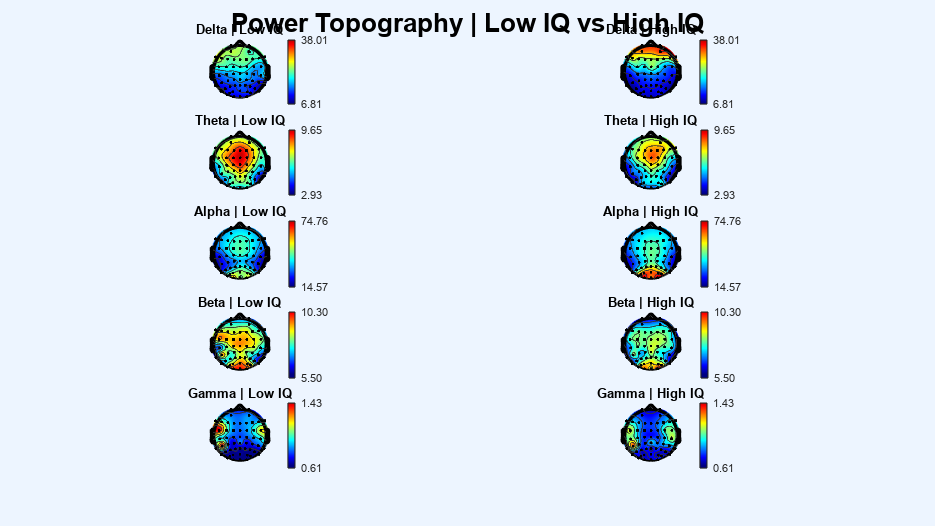

%% Plot 1: Topography Low vs High
figure('Position',[50 50 1500 900],'Color','w');

for b = 1:nBands
    lowValsB  = allTopoLow(b,:);
    highValsB = allTopoHigh(b,:);

    vals = [lowValsB highValsB];
    vals = vals(isfinite(vals));

    if isempty(vals)
        mapLims = [0 1];
    else
        mapLims = [min(vals) max(vals)];
        if mapLims(1) == mapLims(2)
            mapLims = [mapLims(1)-1 mapLims(2)+1];
        end
    end

    lowMin  = min(lowValsB,  [], 'omitnan');
    lowMax  = max(lowValsB,  [], 'omitnan');
    highMin = min(highValsB, [], 'omitnan');
    highMax = max(highValsB, [], 'omitnan');

    subplot(nBands,2,(b-1)*2+1);
    topoplot(lowValsB, loc57, 'electrodes','on', 'style','both', 'maplimits', mapLims, 'conv','on');
    cb = colorbar;
    cb.Limits = mapLims;
    cb.Ticks = [mapLims(1) mapLims(2)];
    cb.TickLabels = {sprintf('%.2f', mapLims(1)), sprintf('%.2f', mapLims(2))};
    title(sprintf('%s | Low IQ', bandNames{b}));

    subplot(nBands,2,(b-1)*2+2);
    topoplot(highValsB, loc57, 'electrodes','on', 'style','both', 'maplimits', mapLims, 'conv','on');
    cb = colorbar;
    cb.Limits = mapLims;
    cb.Ticks = [mapLims(1) mapLims(2)];
    cb.TickLabels = {sprintf('%.2f', mapLims(1)), sprintf('%.2f', mapLims(2))};
    title(sprintf('%s | High IQ', bandNames{b}));
end

sgtitle('Power Topography | Low IQ vs High IQ', 'FontSize', 16, 'FontWeight', 'bold');
print(gcf, 'power_topography_LowHigh_IQ.png', '-dpng', '-r300');

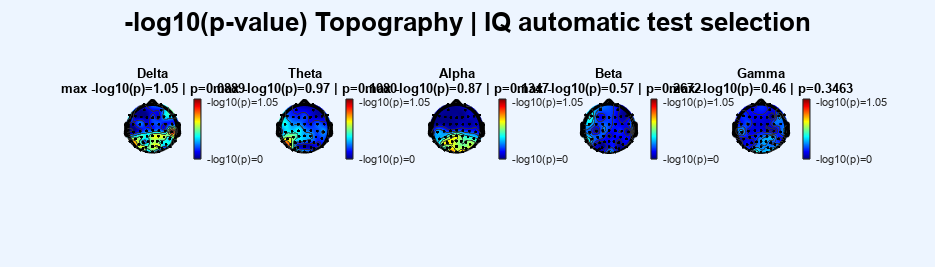


%% Plot 2: -log10(p-value)
figure('Position', [50 50 1400 400], 'Color', 'w');

pMax = max(negLogP(:), [], 'omitnan');
if isempty(pMax) || ~isfinite(pMax) || pMax <= 0
    pMax = 1;
end

for b = 1:nBands
    subplot(1, nBands, b);

    bandData = negLogP(b,:);
    topoplot(bandData, loc57, ...
        'electrodes', 'on', ...
        'maplimits', [0 pMax], ...
        'conv', 'on', ...
        'style', 'both');

    maxNegLogP = max(bandData, [], 'omitnan');
    minP = 10^(-maxNegLogP);

    title(sprintf('%s\nmax -log10(p)=%.2f | p=%.4f', bandNames{b}, maxNegLogP, minP));

    c = colorbar;
    c.Ticks = [0 pMax];
    c.TickLabels = {sprintf('-log10(p)=0'), sprintf('-log10(p)=%.2f', pMax)};
end

sgtitle('-log10(p-value) Topography | IQ automatic test selection', ...
    'FontSize', 16, 'FontWeight', 'bold');
print(gcf, 'negLogP_topography_LowHigh_IQ.png', '-dpng', '-r300');


fprintf('\nDone!\n');


Done!



%% ===== Local function =====

function [isNormal, p] = localNormalityCheck(x)
    x = x(:);
    x = x(isfinite(x));

    if numel(x) < 3
        isNormal = false;
        p = NaN;
        return;
    end

    if std(x) == 0
        isNormal = false;
        p = 0;
        return;
    end

    z = (x - mean(x)) / std(x);
    try
        [~, p] = kstest(z);
    catch
        p = NaN;
    end

    isNormal = ~isnan(p) && p > 0.05;
end